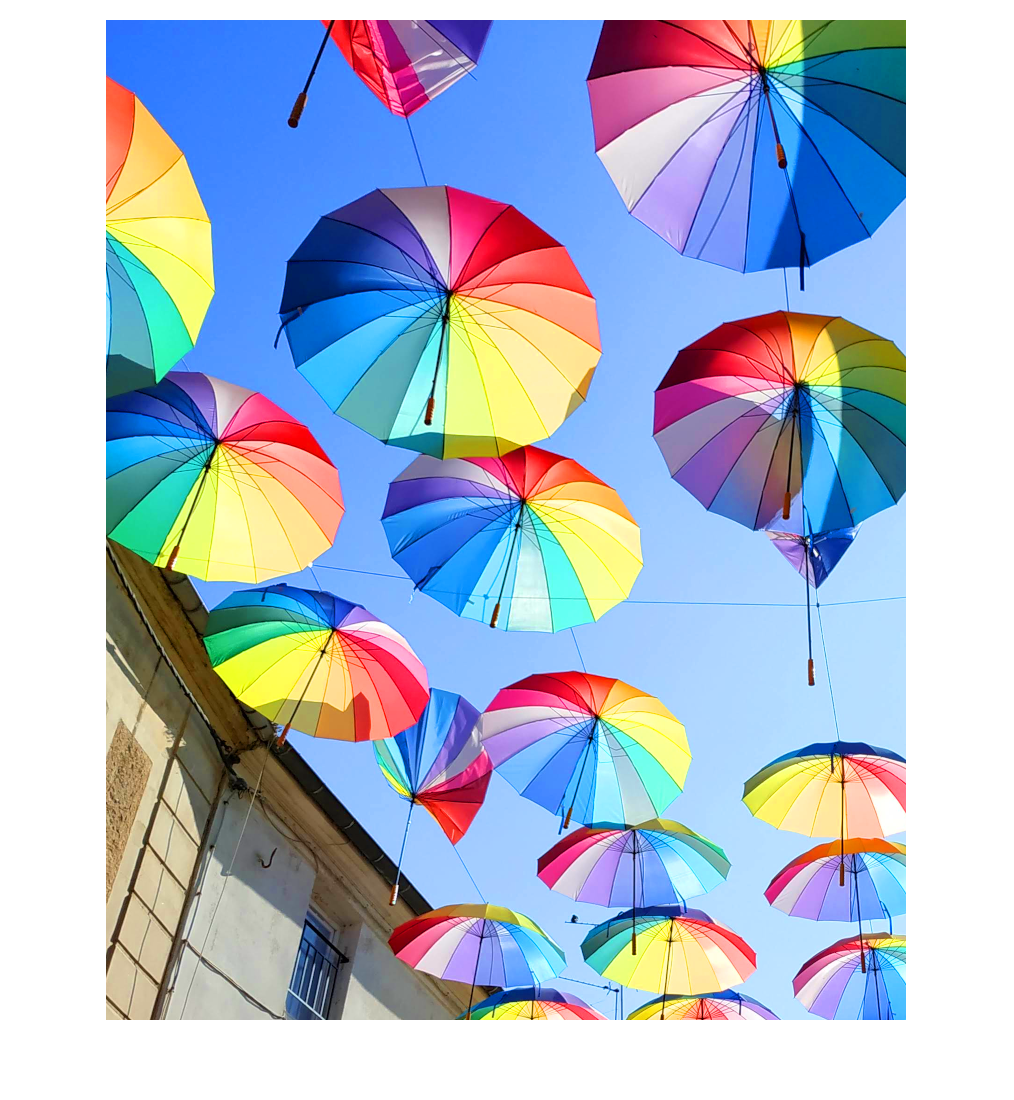

%lettura immagine
try
    %per leggere altre immagini basta modificare la stringa passata a imread()
    RGB= imread('colors.bmp');
catch
    %in caso di errore nella lettura per qualsiasi motivo il programma termina
    error('Impossibile aprire immagine')
end
%mostro immagine
imshow(RGB)

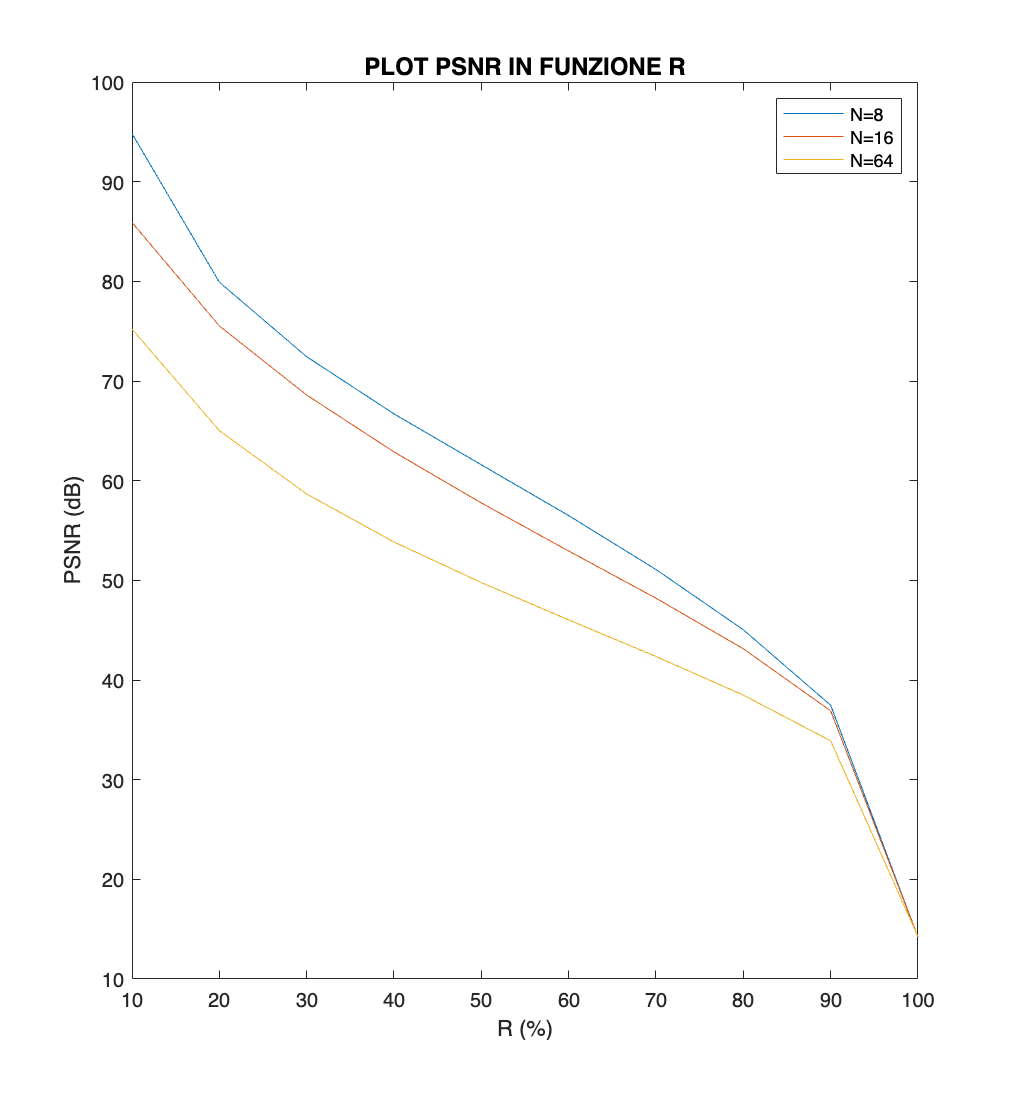


%conversione RGB->YCbCr
YCbCr=rgb2ycbcr(RGB);

%divido nelle componenti
Y=YCbCr(:,:,1);
Cb=YCbCr(:,:,2);
Cr=YCbCr(:,:,3);

%limito valori tra -128 e 127 invece che tra 0 e 255
%scelta fatta perchè il psnr migliora
Y0 = double(Y)-128;
Cb0=double(Cb)-128;
Cr0=double(Cr)-128;

%vettore di N,R,PSNR per fare ciclo
N=[8 16 64];
R=[10 20 30 40 50 60 70 80 90 100];
psnr=[0 0 0 0 0 0 0 0 0 0];

%funzioni lambda per blockproc
fun = @(block_struct) dct2(block_struct.data);
fun2 = @(block_struct) idct2(block_struct.data);

%ciclo per scorrere N
for i=1:3
    %ciclo per scorrere R
    for k=1:10
        %analisi(DCT) a blocchi di dimensione N(i)*N(i)
        DCTY=blockproc(Y0,[N(i) N(i)],fun);
        DCTCb=blockproc(Cb0, [N(i) N(i)], fun);
        DCTCr=blockproc(Cr0, [N(i) N(i)], fun);
        
        %calcolo soglia
        prctY=prctile(abs(DCTY),R(k),"all");
        prctCb=prctile(abs(DCTCb),R(k),"all");
        prctCr=prctile(abs(DCTCr),R(k),"all");
        
        %azzeramento valori minori di prctY
        DCTY(abs(DCTY)<prctY)=0;
        DCTCb(abs(DCTCb)<prctCb)=0;
        DCTCr(abs(DCTCr)<prctCr)=0;
    
        %dct inversa a blocchi e riporto intervallo valori tra 0 e 255
        Yc=blockproc(DCTY,[N(i) N(i)],fun2)+128;
        Cbc=blockproc(DCTCb, [N(i) N(i)], fun2)+128;
        Crc=blockproc(DCTCr, [N(i) N(i)], fun2)+128;
    
        %calcolo errore quadratico medio
        errY = mean((double(Y(:))-double(Yc(:))).^2);
        errCb=mean((double(Cb(:))-double(Cbc(:))).^2);
        errCr=mean((double(Cr(:))-double(Crc(:))).^2);

        %calcolo errore totale
        errT=3/4*errY+1/8*errCb+1/8*errCr;

        %calcolo psnr
        psnr(k)=10*log10(255^2/errT);
    end
    plot(R,psnr)
    %hold on perchè plotto tutti e 3 i casi di N in un unico grafico
    hold on
end
%label e legenda grafico
xlabel('R (%)')
ylabel('PSNR (dB)')
legend('N=8','N=16','N=64')
title('PLOT PSNR IN FUNZIONE R','FontSize',12)
hold off